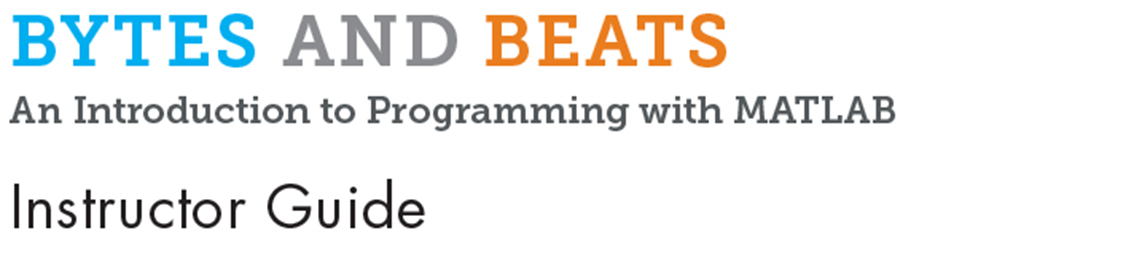

# Module 7: Vectors, Variables, and Functions

**Prerequisite Domain Knowledge:** Variables, vectors, indexing

**Expected Completion Time: **50 minutes

## Vector Math Review

*Expected Duration: 15 minutes*

### Learning Objectives

- Revisit and practice vector math.

### Motivation

Let's revisit calculations with vectors for deeper understanding. This can help us work with sound waves in the form of vectors.

### Materials

- MATLAB®

### Steps

Ask the students to open the below Live Script using the **Command Window. **Have them complete the first section and guide them with the answers below. Discuss the inputs and outputs of each line.

 
open 'Vectors_Variables_Functions.mlx'

Recollect that a numeric vector is used to store similar numeric values in a single variable. It is a collection of numbers. You can add or subtract a single number to/from a vector.  A single number is called a scalar.   

We have used the `:` operator for indexing. It is used to indicate all the numbers in between with a gap of 1. It can also be used to create a vector of numbers as shown.

Ask the students how they would use `y `to get back the original vector `x`. Answer is:

You can multiply or divide a vector with a scalar.  

You can add or subtract two vectors of the same size.

You can multiply or divide two vectors of the same size. In this case, however, you must use **“dot” notation**, which tells MATLAB to perform multiplication operation between the corresponding elements of the two vectors and return a vector.

Let the students try out some more operations on their own. 

## Using Functions

*Expected Duration: 20 minutes*

### Learning Objective

- Understand the syntax for using built-in MATLAB functions

- Use functions with vectors as inputs.

- Use the documentation to get help on functions.

### Motivation

Function is an important programming concept. Let us now formalize this concept before we use some more functions and eventually write one of our own.

### Materials

- MATLAB

### Steps

Explain what a function is, including input, output, and calling syntax.

- A function is a program or code or a group of commands that performs a specific task. In that way, it is like a script. Unlike a script however, a function may take one or more inputs and may return one or more outputs. It has three parts with the following syntax:

- >> <output variable> = <function name>(<input>)

- `<``function name``>` - name of the function you want to execute

- `<``input``>`- this is what the function will be executed on. 

- `<``output variable``>` - this is where the result of the execution is stored.

Using the same Live Script as above, discuss the inputs and outputs of each function:

- Here, we are trying to find the square root of `9`. The function name is `sqrt`. The input is 9 (the number we want to find the square root of) and the result,`3`, is stored in the output variable x. 

- Here, the function `max`, will take the vector `[4 2 9]` as input and return the maximum value in that vector (`9`) stored in the output variable s.

- The `'find'` function takes in a vector of numbers as input and returns indices of the non-zero elements as an output.

- The `'join'`function takes a vector of strings as an input and gives us a single string as an output. We also saw it in the indexing quiz.

- Like `'join'`and `'find'`, MATLAB provides thousands of ready-to-use functions which perform specific tasks like '`sqrt'` which calculates square-root or '`round'` which rounds off the input. Students can try them in the **Command Window**.

- Try passing a vector as input, e.g.

- You can look up a specific function on the documentation such as `sqrt` by using the command

- The doc has syntax of the function. Explain that syntax is basically the spelling and grammar of the function. Explain how the function needs to be used.

- Some popular functions to explore are `plot`, `bar`,` plot3`,` life`,` spy`,` why`.  The `why`,` life`,` and spy` commands are particularly fun! Ask them to doc <function name> to explore some of these.

- You can also write your own functions to use in your programs or share with others. Students will learn to write a function themselves in a later module.

## Playing by Numbers

*Expected Duration: 15 minutes*

### Learning Objective

- Use and experiment with the syntax for using built-in MATLAB functions

- Use functions with vectors as inputs.

### Motivation

Now that the students are familiar with the concept of functions, they can start using some built-in functions to create music for further practice.

### Materials

- MATLAB

### Steps

- We have provided some functions specially for this course. One of them is called '`playNumber'.`

This function takes an array of numbers as input, and for each note it will play a corresponding tone on the speaker, one after another.   

Tell the students to execute the following commands along with you in the Live Script:

- Give the students time to explore creating vectors and playing notes. Ask them what they think the function does. How is the input related to the output? 

- The function plays a sound whose pitch (and hence, frequency) is related to the numbers. In fact, they are notes arranged in increasing order of frequency according to the even-tempered scale.

- Some things that the students can try:

- Try out numbers above 8 and below 1.

- Create a simple tune for a song like “Twinkle Twinkle Little Stars” or “Somewhere Over the Rainbow.”

- Once the students have a tune, ask them to move the song up or down an octave.

**Note:** If the array/vector gets too long, the function could be playing the notes for a long time. To exit the function, press the keys **Ctrl + C **simultaneously.

**Helper Functions **(do not edit)

function playNumber(varargin)
% Play sine wave of frequency corresponding to input number
% playNumber(num)
% playNumber(num, time)

in1 = varargin{1};
notes = in1(1,:);

if nargin == 2
    d = varargin{2};  % duration (length) of note in seconds (set by user)
else
    d = 0.75;         % duration (length) of note in seconds (set automatically)
end

scale = [16.3500000000000;18.3500000000000;20.6000000000000;21.8300000000000;24.5000000000000;27.5000000000000;30.8700000000000;32.7000000000000;36.7100000000000;41.2000000000000;43.6500000000000;49;55;61.7400000000000;65.4100000000000;73.4200000000000;82.4100000000000;87.3100000000000;98;110;123.470000000000;130.810000000000;146.830000000000;164.810000000000;174.610000000000;196;220;246.940000000000;261.630000000000;293.660000000000;329.630000000000;349.230000000000;392;440;493.880000000000;523.250000000000;587.330000000000;659.250000000000;698.460000000000;783.990000000000;880;987.770000000000;1046.50000000000;1174.66000000000;1318.51000000000;1396.91000000000;1567.98000000000;1760;1975.53000000000;2093;2349.32000000000;2637.02000000000;2793.83000000000;3135.96000000000;3520;3951.07000000000;4186.01000000000;4698.63000000000;5274.04000000000;5587.65000000000;6271.93000000000;7040;7902.13000000000;];
%scale = scaleTotal(29:end);  % this is a C-major scale, with C4 = scale(1), D4 = scale(2), ... C5 = scale(8) etc. 


for k = notes
    try 
        f0 = scale(k+28);           % fundamental frequency (Hz)
        sf = 22050;                 % sample frequency (Hz)
        s = (0:1/sf:d);             % sound data preparation
        s = sin(2*pi*f0* s);        % sinusoidal modulation
        sound(s, sf);               % sound presentation
        wait = d/6; 
        pause(d + wait);
    catch
        error('You can only play whole numbers which are between -28 and 36.')
    end
             % waiting for sound end
end

end

© COPYRIGHT 2024 by The MathWorks®, Inc.